
clear;
close all; clc

%% PRE-STEP #1:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Get the path of the current directory and construct the path
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

src_path = fullfile(pwd, 'src');
addpath(genpath(src_path))


%% PRE-STEP #2:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  -> Import on-orbit data from subfolder /data
%  -> Select orbit propagation time duration by deciding number fo orbits
%  -> Data pre-processing was done by skipping some points in q_data due to
%     acquisition frequecy difference (q: 1/64 freq)  
%  -> Data needed:
%        1. quaternion
%        2. Groundtrack (latitude & longitude)
%        3. Sun vector
%        4. Eclipse
%
%% NOTE:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Quaternions here are defined in a specific frame of reference 
%  Import LVLH2BODY quaternion 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

global orbit;
orbit = 2;

period = orbit*2*pi*sqrt(6878^3/398600);
time = round(period/64);

data = importdata("data/fs7t_SE_Q_LVLH2BODY_2024050090000_2024051090000_A.xls");

q_data = data.data(2:16:time*16,1:4);

GROUND = importdata("data/fs7t_SE_LON_LAT_2024050090000_2024051090000_A.xls");

dates = GROUND.textdata(1:time,1);
GEO(:,1) = GROUND.data(1:time,1); % latitude
GEO(:,2) = GROUND.data(1:time,2); % longitude


SUN = importdata("data/fs7t_SE_SUN_VECTOR_2024050090000_2024051090000_A.xls");

sun_vec = [SUN.data(1:time,1), SUN.data(1:time,2), SUN.data(1:time,3)];

ECP = importdata("data/fs7t_SE_ECLIPSE_2024050090000_2024051090000_A.xls");

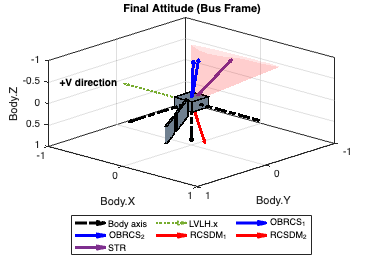

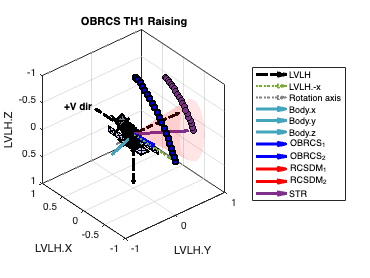

Flag_Ecp = ECP.data(1:time,1);



%% STEP #1:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Flag to decide SQAA mode
%     @param Flag_view --> animate with earth blockage cone
%                            0 : no cone
%                            1 : animate with cone
%     @param Flag_prop --> use imported data to animate
%                            0 : No (use single quaternion)
%                            1 : Yes, use sets of quaternion
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Flag_View = 0;

Flag_prop = 0;



%% RESULT:%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Run the ATTITUDE_animation function below to view the result
%
%  INPUT:
%   @param Q          -->  (1x4)     Quaternion applied to target vector
%   @param component  -->  (string)  Component wish to observe
%                                    List:
%                                    1. OBRCS_1
%                                    2. OBRCS_2
%                                    3. RCSDM_1
%                                    4. RCSDM_2 (disable, default 3.)
%                                    5. Star Tracker (on as default)
%   @param Flag       -->  (1x3)     Flags defined in STEP #1 and eclipse
%   @param other      --> 
%   @param string     -->  (string)  Desired plot name
%
%  OUTPUT:
%   THR_TRACE  :  Selected thruster vector trace
%   STR_TRACE  :  Star Tracker vector trace
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


if Flag_prop == 1
    q = q_data;

else
    % raising, OB1_part
    q = [0.1600 0.7055 0.2057 0.6591];

end

string = 'OBRCS TH1 Raising';
component = 'OBRCS_1';
Flag = {Flag_prop, Flag_View, Flag_Ecp};
other = {GEO, sun_vec};


% MAIN
[THR_TRACE, STR_TRACE] = SAAS(q, component, Flag, other, string, dates{1});